%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 该脚本用于计算 photocurrent map
% 参考文献 : Photo-Nernst current in graphene
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1-1 基本参数设定
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
unit_len = 0.1; % 一个像素的长度对应 0.1微米
np_L = 40; % x方向的像素点，对应 4微米
np_W = 20; % y方向的像素点，对应 2微米
np_node = (np_L + 1) * (np_W + 1);
np_unit = np_L * np_W;

几何构型

node_list = zeros(np_node, 2);
neighbor_list = zeros(np_unit, 4);

% 确定所有节点的坐标
count = 0;
for i = 0:np_L
    x_now = i;
    for j = 0:np_W
        y_now = j;
        count = count + 1;
        node_list(count, :) = [x_now, y_now];
    end
end

% 确定所有单元涉及的节点指标
count = 0;
for i = 0:(np_L - 1)
    for j = 1:np_W
        index_ld = i * (np_W + 1) + j;
        
        count = count + 1;
        neighbor_list(count, :) = [index_ld, index_ld + 1, index_ld + np_W + 2, index_ld + np_W + 1];
    end
end

% y = 0 的边界
bound_y_down_list = find(node_list(:, 2) == 0);
% y = W 的边界
bound_y_up_list = find(node_list(:, 2) == np_W);
% x = 0 的边界
bound_x_left_list = find(node_list(:, 1) == 0);
% x = L 的边界
bound_x_right_list = find(node_list(:, 1) == np_L);

网格可视化

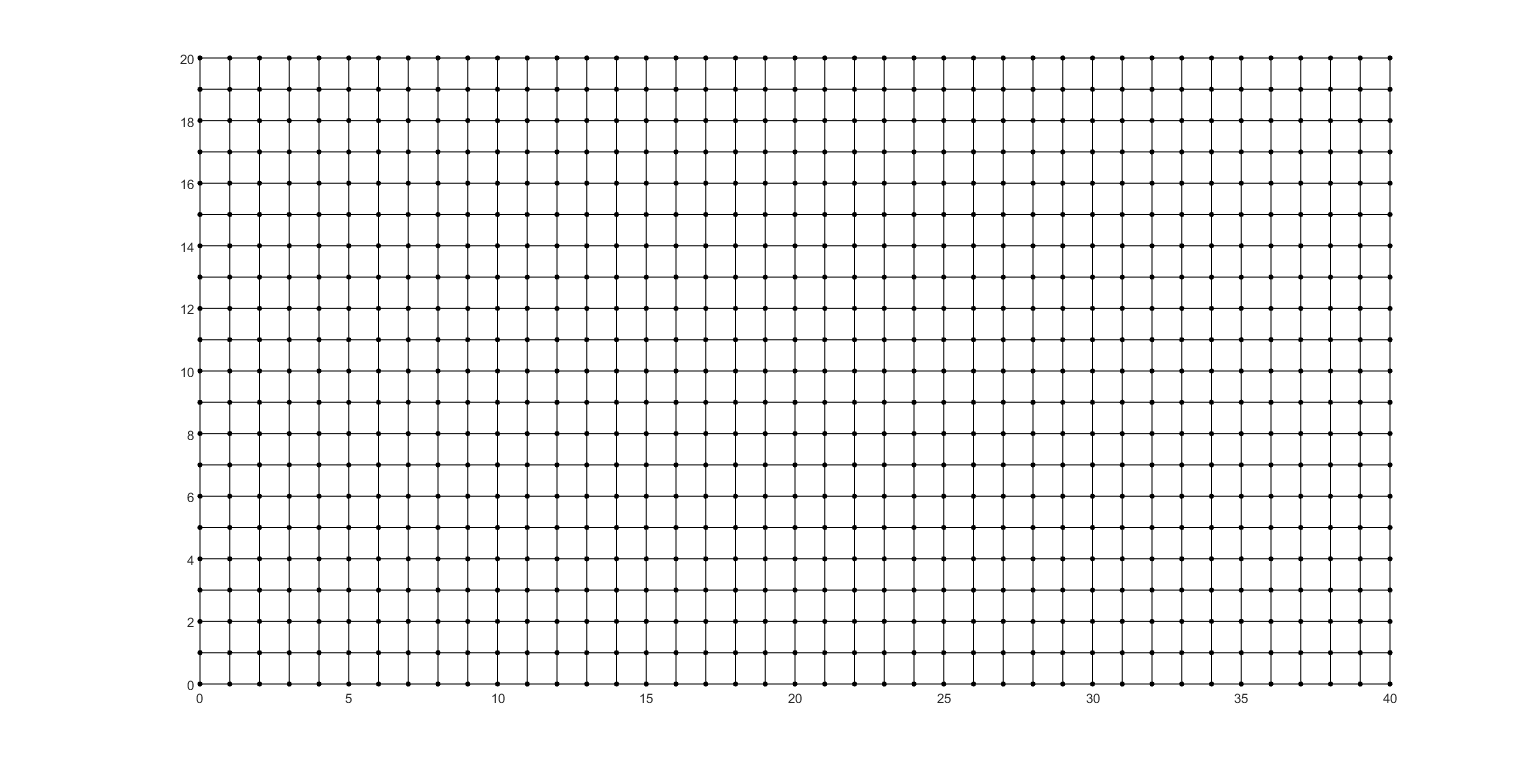

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1-3 网格可视化
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fig1 = figure;
set(gcf, 'unit', 'inch', 'position', [10, 5, 16.00, 8.00]) % figure
patch('Faces', neighbor_list, 'Vertices', node_list, 'FaceColor', 'white');      
hold on
scatter(node_list(:,1), node_list(:,2), 16, 'ko', 'filled')

参数设定

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 2-1 基本参数设定
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
kappa = 100; % in-plane thermal conductivity of graphene on SiO2 单位是 W / (K·m)
interlayer_dist = 0.35; % thickness of graphene 单位是nm
lambda = kappa * interlayer_dist * 10^(-9);
lambda = lambda * 100; % 单位变为 W / (K·um^2)
G = 1000; % thermal coupling between graphene and the SiO2 substrate 单位是 W / (K·cm^2)
G = G / 10^8; % 转换到 (mu m) 微米尺度

gamma = 1; % absorption coefficient，指graphene从laser spot中汲取能量的效率
P0 = 40; % peak intensity of power, 每单位面积的发热功率，单位是 mu W
P0 = P0 * 10^(-6); % 转换到 (W) 瓦
power_material = gamma * P0;
r0 = 6; % laser spot的半径大小，r0 = 6 指半径为0.6微米

有限元矩阵的计算

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 3-1 准备工作
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 计算 形函数 和 形函数偏导 的矩阵
order_gauss = 1; % 高斯求积的阶数
[gauss_points_list, A_coeff_list] = get_gauss_points(order_gauss);
[std_shape_mat, std_shape_partial_mat] = get_jacobi_order1(gauss_points_list);

% Jacobi矩阵
Jacobi_mat = zeros(2, 2);
lambda_coeff_mat = diag([lambda, lambda]); % 这里是导热系数

计算 K_cond 和 K_coupling

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 3-2 体内的有限元矩阵
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
K_cond = zeros(np_node, np_node); % heat conductive
K_coupling = zeros(np_node, np_node); % thermal coupling

for ii = 1:np_unit
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 得到当前四边形的四个节点的指标和节点上的函数值
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    unit_node_indexes = neighbor_list(ii, :);
    unit_node_pos_list = [node_list(unit_node_indexes(1),:); ...
                          node_list(unit_node_indexes(2),:); ...
                          node_list(unit_node_indexes(3),:); ...
                          node_list(unit_node_indexes(4),:)];
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 计算 K_cond / F_cond 的矩阵
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 得到 K_unit 和 FS
    K_cond_unit = zeros(4, 4);
    K_coupling_unit = zeros(4, 4);
    
    % 累加 K_cond_unit 和 F_unit
    for jj = 1:2
        r_j = gauss_points_list(jj);
        A_j = A_coeff_list(jj);
        for kk = 1:2
            s_k = gauss_points_list(kk);
            A_k = A_coeff_list(kk);
            
            % 计算 Gauss point点处的Jacobi矩阵 及 其行列式的绝对值
            Jacobi_mat = squeeze(std_shape_partial_mat(:, :, jj, kk)) * unit_node_pos_list; % 该高斯点处的 Jacobi 矩阵
            det_Jacobi_mat = abs(det(Jacobi_mat));
            J_inv_N_partial_mat = Jacobi_mat \ squeeze(std_shape_partial_mat(:, :, jj, kk)); % J^{-1} * \partial_N
            
            % 累加 K_cond_unit 和 F_unit
            K_cond_unit = K_cond_unit + A_j * A_k * det_Jacobi_mat * (J_inv_N_partial_mat)' * J_inv_N_partial_mat;
            K_coupling_unit = K_coupling_unit + A_j * A_k * det_Jacobi_mat * std_shape_mat(:, jj, kk) * transpose(std_shape_mat(:, jj, kk));
        end
    end
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 将 K_cond_unit 和 F_unit 组装进 K_cond 和 F_cond 矩阵中
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    for jj = 1:4
        for kk = 1:4
            K_cond(unit_node_indexes(jj), unit_node_indexes(kk)) = K_cond(unit_node_indexes(jj), unit_node_indexes(kk)) + K_cond_unit(jj, kk);
            K_coupling(unit_node_indexes(jj), unit_node_indexes(kk)) = K_coupling(unit_node_indexes(jj), unit_node_indexes(kk)) + K_coupling_unit(jj, kk);
        end
    end
    
end

将K_cond与K_coupling相加

KG = lambda * K_cond + G * K_coupling;

laser spot visualization

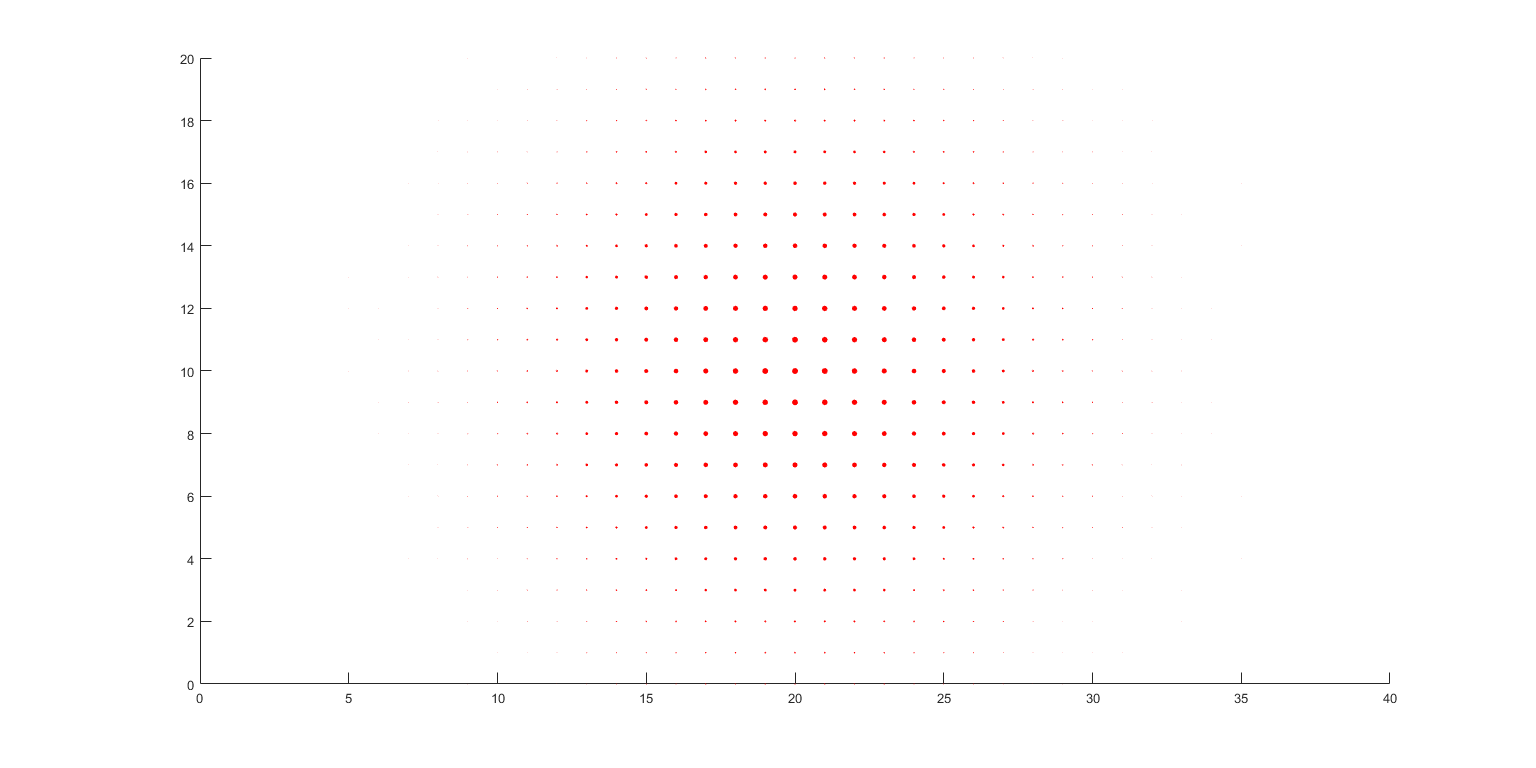

center_x = round(np_L / 2);
center_y = round(np_W / 2);
laser_heat_list = zeros(np_node, 1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4-1 take the laser spot to have a Gaussian shape
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
count = 0;
for ii = 0:np_L
    for jj = 0:np_W
        count = count + 1;
        r2_now = (ii - center_x)^2 + (jj - center_y)^2;
        laser_heat_list(count) = exp(- r2_now / r0^2);
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 4-2 激光热源可视化
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fig1 = figure;
set(gcf, 'unit', 'inch', 'position', [10, 5, 16.00, 8.00]) % figure
scatter(node_list(:,1), node_list(:,2), laser_heat_list * 20, 'ro', 'filled')

计算 photo_current map

photo_current_list = zeros(np_node, 1);
% F_power = zeros(np_node, 1); % heat power of laser
T_diff_list = zeros(np_node, 1); % the average temperature difference between the two free edges as a function of laser spot position

for node_index = 1:np_node
    F_power = zeros(np_node, 1); % heat power of laser
    center_x = node_list(node_index, 1);
    center_y = node_list(node_index, 2);
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 4-1 take the laser spot to have a Gaussian shape
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    count = 0;
    for ii = 0:np_L
        for jj = 0:np_W
            count = count + 1;
            r2_now = (ii - center_x)^2 + (jj - center_y)^2;
            laser_heat_list(count) = exp(- r2_now / r0^2);
        end
    end
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 4-2 得到 F 向量
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    for ii = 1:np_unit
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % 得到当前四边形的四个节点的指标和节点上的函数值
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        unit_node_indexes = neighbor_list(ii, :);
        
        unit_node_pos_list = [node_list(unit_node_indexes(1),:); ...
                              node_list(unit_node_indexes(2),:); ...
                              node_list(unit_node_indexes(3),:); ...
                              node_list(unit_node_indexes(4),:)];
        
        power_list = [laser_heat_list(unit_node_indexes(1),:); ...
                      laser_heat_list(unit_node_indexes(2),:); ...
                      laser_heat_list(unit_node_indexes(3),:); ...
                      laser_heat_list(unit_node_indexes(4),:)];
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % 计算 K_cond / F_cond 的矩阵
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % 得到 F_unit
        F_unit = zeros(4, 1);

        % 累加 K_unit 和 F_unit
        for jj = 1:2
            r_j = gauss_points_list(jj);
            A_j = A_coeff_list(jj);
            for kk = 1:2
                s_k = gauss_points_list(kk);
                A_k = A_coeff_list(kk);

                % 计算 Gauss point点处的Jacobi矩阵 及 其行列式的绝对值
                Jacobi_mat = squeeze(std_shape_partial_mat(:, :, jj, kk)) * unit_node_pos_list; % 该高斯点处的 Jacobi 矩阵
                det_Jacobi_mat = abs(det(Jacobi_mat));

                % 累加 K_unit 和 F_unit

                F_unit = F_unit + A_j * A_k * det_Jacobi_mat * std_shape_mat(:, jj, kk) * transpose(std_shape_mat(:, jj, kk));
            end
        end

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % 将 K_unit 和 F_unit 组装进 K_cond 和 F_cond 矩阵中
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        for jj = 1:4
            F_power(unit_node_indexes(jj)) = F_power(unit_node_indexes(jj)) + F_unit(jj);
        end
    end
    F_power = F_power * power_material;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 4-3 添加自然边界条件
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    for boundary_index = 1:(np_W + 1)
        % 左边
        bd_left_index = bound_x_left_list(boundary_index);
        KG(bd_left_index, :) = 0;
        KG(bd_left_index, bd_left_index) = 1;
        F_power(bd_left_index) = 0;
        
        % 右边
        bd_right_index = bound_x_right_list(boundary_index);
        KG(bd_right_index, :) = 0;
        KG(bd_right_index, bd_right_index) = 1;
        F_power(bd_right_index) = 0;
    end
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 4-4 计算温度分布
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    T_vec = KG \ F_power;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % 4-5 calculate the average temperature difference between the two free
    % edges
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    T_diff = 0;
    for boundary_index = 1:(np_L + 1)
        % 上边温度
        bd_up_index = bound_y_up_list(boundary_index);
        T_up = T_vec(bd_up_index);
        
        % 下边温度
        bd_down_index = bound_y_down_list(boundary_index);
        T_down = T_vec(bd_down_index);
        
        T_diff = T_diff + (T_down - T_up);
    end
    T_diff = T_diff / (np_L + 1);
    T_diff_list(node_index) = T_diff;
end